# Lab 1

Dr. Amr Amin

Ahmed Alqassas

Autumn 2024-25

## Digital Images

A digital image is composed of a finite number of elements, each of which has a particular location and value, called Pixels.

## **Digital Images Formation**

**1 Sampling** converts continuous signal into discrete signal, so that it can be quantized. Sampling rate is the frequency at which a signal is sampled.

**Nyquist ratio:** A good sampling rate must be twice the highest frequency of the signal.

**2 Quantization** limits the number of allowed amplitude values, so that a computer can interprent them.

Note: Analog signals are not necessarily continuous. Digital signals are  not necessarily discrete.

## Images in MATLAB

MATLAB stores images in [*matrices*](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html?searchHighlight=matrix&s_tid=srchtitle_support_results_1_matrix), in which each *element* of the matrix corresponds to a *single pixel* in the displayed image. 

## Import an image with `imread`

The function `imread` impots an image into into MATLAB [Workspace](https://www.mathworks.com/help/matlab/learn_matlab/workspace.html?searchHighlight=workspace&s_tid=srchtitle_support_results_1_workspace).

rgb_img = imread("peppers.png");

now the data in the `pepper.png` image is stored in the matrix [variable](https://www.mathworks.com/help/matlab/matlab_prog/variable-names.html?searchHighlight=variables&s_tid=srchtitle_support_results_1_variables) named `rgb_img`.

## Show an image using `imshow`

The function `imshow` can visualize the data in the` rgb_img` matrix variable.

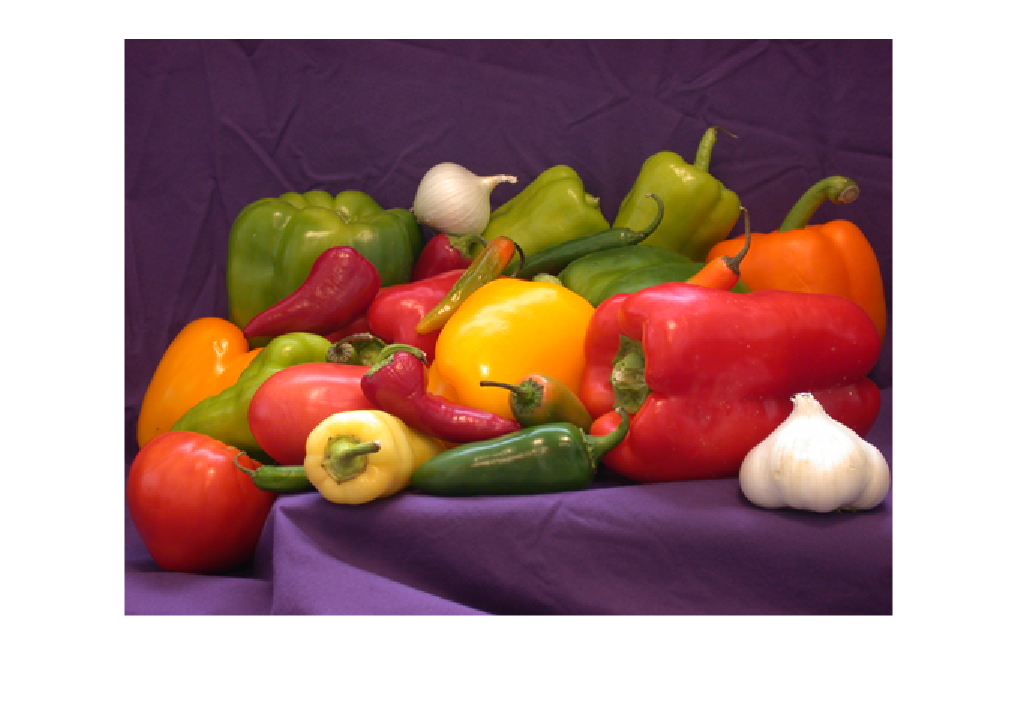

imshow(rgb_img);

## Convert an RGB (Truecolor) image into Grayscale (Intensity)

For demonestration reasons, we will convert the `rgb_img` into grayscale. This is done using `rgb2gray` function.

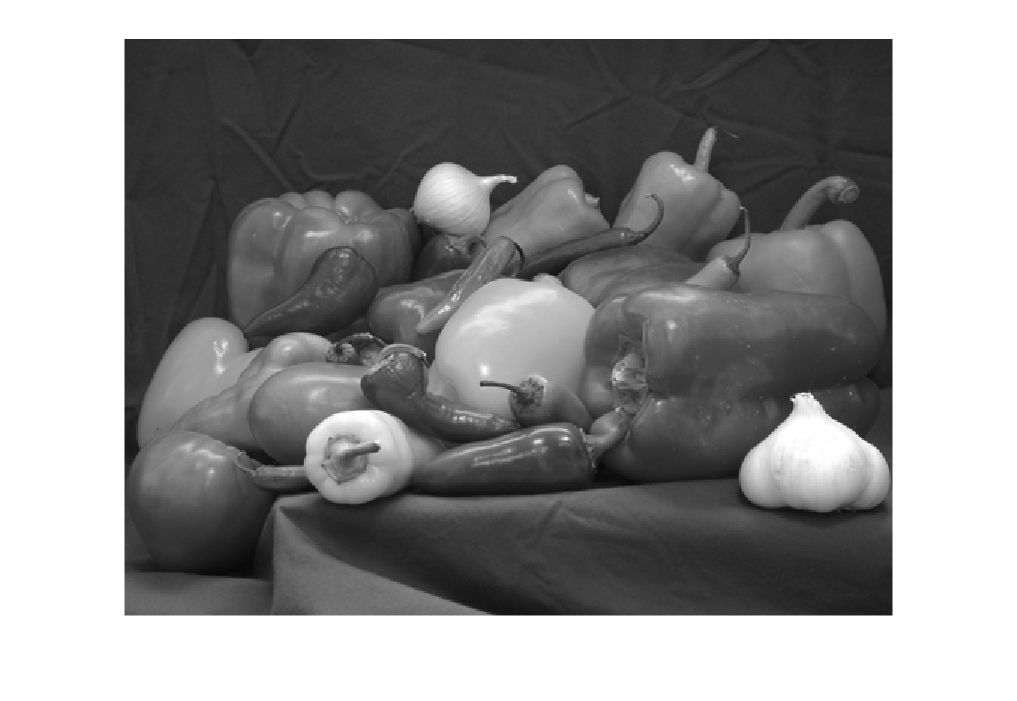

gray_img = rgb2gray(rgb_img); 
imshow(gray_img);

## Size of images in Workspace

The size of an image = rows x columns. you can use the `size` function to view the size.

size(gray_img) % We ommited the ';' so that the answer appears instantly.

ans =    384   512


The [`ans`](https://www.mathworks.com/help/matlab/ref/ans.html?searchHighlight=ans&s_tid=srchtitle_support_results_1_ans) shows that the size is `384 512.` This means the `gray_img` matrix contains 384 rows and 512 columns.

Let's check the size of the `rgb_img` 

size(rgb_img)

ans =    384   512     3


The [`ans`](https://www.mathworks.com/help/matlab/ref/ans.html?searchHighlight=ans&s_tid=srchtitle_support_results_1_ans) shows that the size is `384 512 3`. **What is this 3?**

**In RGB the image is stored in 3 matrices correponding to Red, Green and Blue intensity levels, forming a 3d matrix. Hence, the number 3 refers to the number of channels in the image. There are other image types that store image information in multiple channels. We will discuss them later.**

## Other information about images

you can use the whos function to get more information about your image other than size. here is an example:

whos("rgb_img") % pay attention to the double quotation.

  Name           Size                Bytes  Class    Attributes

  rgb_img      384x512x3            589824  uint8              



We already knew the name and size, let's discuss Bytes and Class.

- **Class** tells you how many Bytes per element are used (Bit-depth). `uint8` means that 8 bits are used to represent each element.

- **Bytes** tells you that the image occupies **589,824 **bytes (0.59 MB) in the MATLAB workspace. **Not** the file size on device storage.

## Example

Determine the number of bytes necessary to store an *uncompressed* RGB color image of size 640 × 480 pixels using 8, 12,16, and 64 bits per color channel.

store_8 = 384 * 512 * 3 * (8/8); % 589,824
store_12 = 384 * 512 * 3 * (12/8); % 884,736
store_16 = 384 * 512 * 3 * (16/8); % 1,179,648
store_64 = 384 * 512 * 3 * (64/8); % 4,718,592

## Split the image into channels

`imsplit` splits multichannel image into its individual channels.

returns a set of k images representing the individual channels in the k-channel image `I`.

[R, G, B] = imsplit(rgb_img);

## Colorizing the channels for RGB

allBlack = zeros(size(rgb_img,1,2),class(rgb_img));
justR = cat(3,R,allBlack,allBlack);
justG = cat(3,allBlack,G,allBlack);
justB = cat(3,allBlack,allBlack,B);

## Visualize the results

There are many ways to show the output. However, it is easier to use the `montage` function in this case.

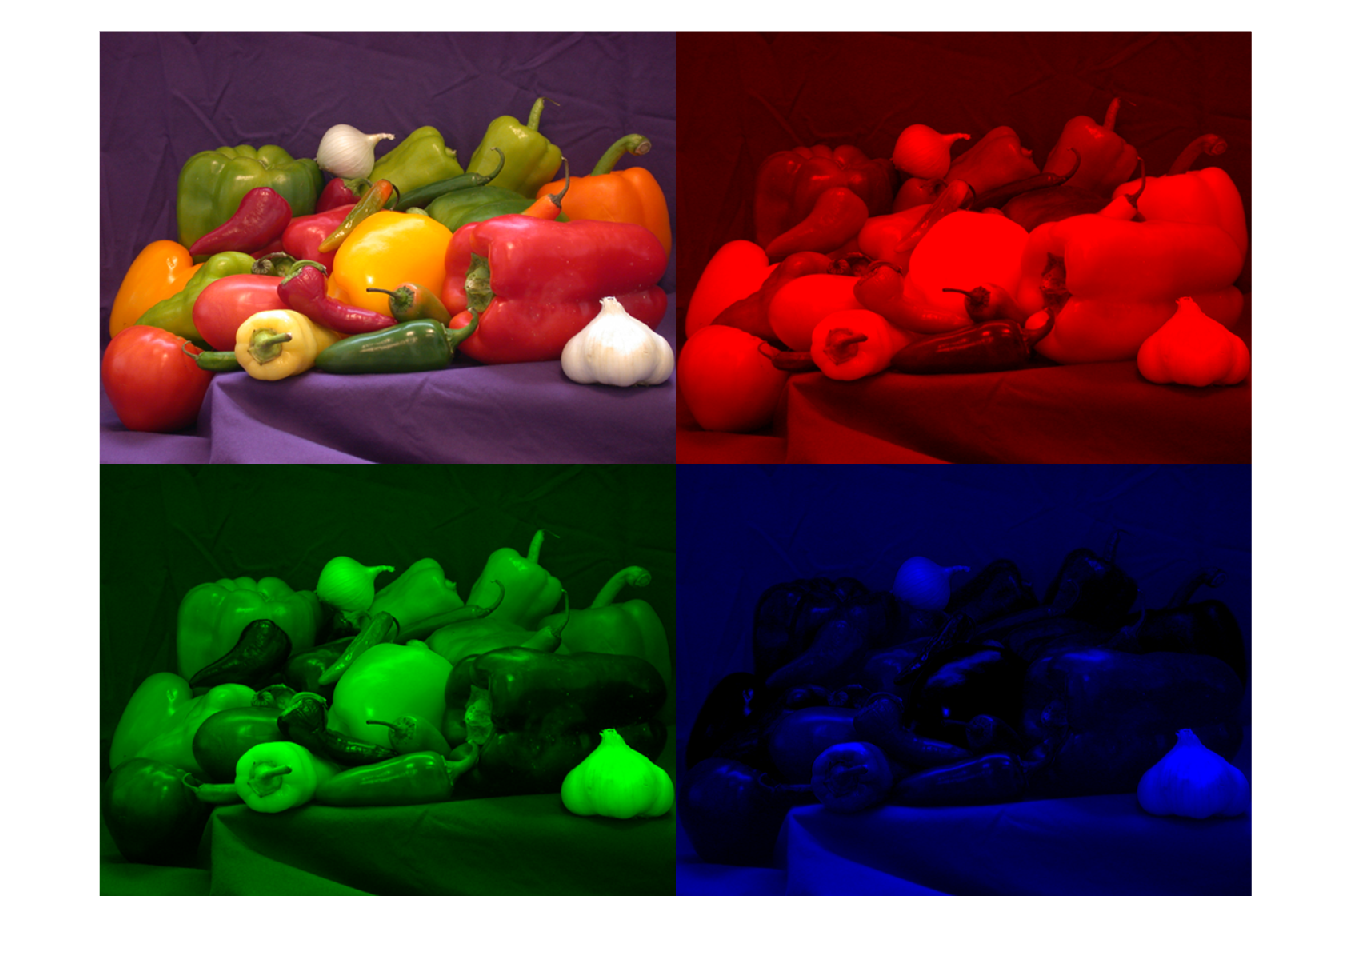

montage({rgb_img, justR, justG, justB}, 'Size', [2 2]);

## Save the result

imwrite(justR, "r.png");
imwrite(justG, "g.png");
imwrite(justB, "b.png");

## Summary